# DLRX draft

github@hnxj; github@dynasim

## 0. Initialization

clear;close all;clc;
PathToDynaSim = 'D:\Modeling\'; % Change it based on your local path for dynasim 
cd(PathToDynaSim);
addpath(genpath('DynaSim'));
cd('DynaSim');

study_dir = 'dlModels/CX1';

eqns={
  'dV/dt = (- V) .* (abs(V) > 100) + (Iapp * (rand(1, N_pop) > .5))*abs(cos(2*pi*omega*t))*((t > t0 & t < t1) | (t > (1000 + t0) & t < (1000 + t1))) + @current + noise*abs(randn(1, N_pop)); noise = 0; t0 = 500; t1 = 1000; Iapp = 0; omega = 1; V(0) = -70*rand(1, N_pop);'
};

% Control current drive for direct stimulation purposes

nES = 70;
nIF = 15;
nIS = 15;

gGABAslow = 0.2;
gGABAfast = 0.2;
gAMPAfar = 0.1;
gAMPAclose = 0.1;
gNMDA = 0.2;

gGABA = 0.2;
gAMPA = 0.1;

tauGABAslow = 50*(1 + .1*randn(1)); % Receptor synaptic decay time constants; SST->~10Hz ~(1/2t = 1/100)
tauGABAfast = 50*(1 + .1*randn(1)); % PV->~100Hz (1/10)
tauAMPAnear = 50*(1 + .1*randn(1)); % PY->~50.0Hz (1/20)
tauAMPAfar = 50*(1 + .1*randn(1)); % PY->~25.0Hz (1/40)

eNoise = 10;
fNoise = 10;
sNoise = 10;

cCoeff = 0.2;

kEE = rand(nES, nES) * cCoeff;
kEIf = rand(nES, nIF) * cCoeff;
kEIs = rand(nES, nIS) * cCoeff;

kIfE = rand(nIF, nES) * cCoeff;
kIfIf = rand(nIF, nIF) * cCoeff;
kIfIs = rand(nIF, nIS) * cCoeff;

kIsE = rand(nIS, nES) * cCoeff;
kIsIf = rand(nIS, nIF) * cCoeff;
kIsIs = rand(nIS, nIS) * cCoeff;

s=[];
s.populations(1).name='ES';
s.populations(1).size=nES;
s.populations(1).equations=eqns;
s.populations(1).mechanism_list={'iNa','iK', 'ileak'};
s.populations(1).parameters={'gNa',120,'gK',36, 'gleak', 0.2,'noise',eNoise};

s.populations(2).name='INSfast';
s.populations(2).size=nIF;
s.populations(2).equations=eqns;
s.populations(2).mechanism_list={'iNa','iK', 'ileak'};
s.populations(2).parameters={'gNa',120,'gK',36, 'gleak', 0.2,'noise',fNoise};

s.populations(3).name='INSslow';
s.populations(3).size=nIS;
s.populations(3).equations=eqns;
s.populations(3).mechanism_list={'iNa','iK', 'ileak'};
s.populations(3).parameters={'gNa',120,'gK',36, 'gleak', 0.2,'noise',sNoise};

s.populations(1).name='ED';
s.populations(1).size=nES;
s.populations(1).equations=eqns;
s.populations(1).mechanism_list={'iNa','iK', 'ileak'};
s.populations(1).parameters={'gNa',120,'gK',36, 'gleak', 0.2,'noise',eNoise};

s.populations(2).name='INDfast';
s.populations(2).size=nIF;
s.populations(2).equations=eqns;
s.populations(2).mechanism_list={'iNa','iK', 'ileak'};
s.populations(2).parameters={'gNa',120,'gK',36, 'gleak', 0.2,'noise',fNoise};

s.populations(3).name='INDslow';
s.populations(3).size=nIS;
s.populations(3).equations=eqns;
s.populations(3).mechanism_list={'iNa','iK', 'ileak'};
s.populations(3).parameters={'gNa',120,'gK',36, 'gleak', 0.2,'noise',sNoise};

s.connections(1).direction='INfast->ES';
s.connections(1).mechanism_list={'iGABAa'};
s.connections(1).parameters={'tauR', tauGABAfast/40, 'tauD',tauGABAfast,'gGABAa',gGABAfast, 'netcon', kIfE};

s.connections(2).direction='ES->INfast';
s.connections(2).mechanism_list={'iAMPA'};
s.connections(2).parameters={'tauR', tauAMPAnear/20, 'tauD',tauAMPAnear,'gAMPA',gAMPAfar, 'netcon', kEIf};

s.connections(3).direction='INslow->ES';
s.connections(3).mechanism_list={'iGABAa'};
s.connections(3).parameters={'tauR', tauGABAslow/20, 'tauD',tauGABAslow,'gGABAa',gGABAslow, 'netcon', kIsE};

s.connections(4).direction='ES->INslow';
s.connections(4).mechanism_list={'iAMPA'};
s.connections(4).parameters={'tauR', tauAMPAfar/10, 'tauD',tauAMPAfar,'gAMPA',gAMPAfar, 'netcon', kEIs};

s.connections(5).direction='INslow->INfast';
s.connections(5).mechanism_list={'iGABAa'};
s.connections(5).parameters={'tauR', tauGABAslow/10, 'tauD',tauGABAslow,'gGABAa',gGABAslow, 'netcon', kIsIf};

s.connections(6).direction='INslow->INslow';
s.connections(6).mechanism_list={'iGABAa'};
s.connections(6).parameters={'tauR', tauGABAslow/10, 'tauD', tauGABAslow,'gGABAa',gGABA, 'netcon', kIsIs};

s.connections(7).direction='INfast->INslow';
s.connections(7).mechanism_list={'iGABAa'};
s.connections(7).parameters={'tauR', tauGABAfast/40, 'tauD',tauGABAfast,'gGABAa',gGABAfast, 'netcon', kIfIs};

s.connections(8).direction='INfast->INfast';
s.connections(8).mechanism_list={'iGABAa'};
s.connections(8).parameters={'tauR', tauGABAfast/40, 'tauD',tauGABAfast,'gGABAa',gGABA, 'netcon', kIfIf};

s.connections(9).direction='ES->ES';
s.connections(9).mechanism_list={'iAMPA'};
s.connections(9).parameters={'tauR', tauAMPAnear/10, 'tauD',tauAMPAnear,'gAMPA',gAMPA, 'netcon', kEE};%%

RunDuration = 1500; % In ms (miliseconds)
vary = {'ES', 'Iapp', [0 5]};

data = dsSimulate(s, 'tspan', [0 RunDuration], 'downsample_factor', 10, ...
                     'solver', 'euler', 'dt', .1, ...
                     'compile_flag', 1, 'parallel_flag', 1, ...
                     'vary', vary, 'verbose_flag', 1);


PREPARING STUDY:
Creating study directory: D:\Modeling\DynaSim\study_20250115110435
Creating data directory: D:\Modeling\DynaSim\study_20250115110435\data
Creating results directory: D:\Modeling\DynaSim\study_20250115110435\results
saving study file: D:\Modeling\DynaSim\study_20250115110435\studyinfo.mat
Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 12 workers.
> In dsApplyModifications>modify_specification (line 188)
In 

dsPlot(data, 'plot_type', 'raster');

dl = DynaLearn(s, study_dir, 'mex', 'PN', 1);
dl.dlSave();

id = 5;
dl = DynaLearn.dlLoader(char("dlModels/PN" + num2str(id)));

DL object loaded from dlModels/PN5 
Params.mat file loaded from dlModels/PN5 
--------
--->Constructing graph ... Done.

Reinitialized.


x = load("matdata\PoGLO_Ca_0818_MTMST.mat").y;
x = x.sigsb2l;

RunDuration = 1500;

[inp1, inp2] = dlOnOffInputs(RunDuration, 500, 1000, 8);
dlInputParameters = {inp1, inp2}; % Null inputs (no external stimulation).
dlOutputParameters = {['ES', '_V'], 1:70, [1 RunDuration], 'afr'};
dlTargetParameters = {{'LogCor2', 1, targetVsgram(:, 1:7), 1, 0, 100}, {'LogCor2', 1, targetVsgram, 1, 0, 100}};

% Define training options
dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure

dlTrainOptions('dlBatchs') = 2;
dlTrainOptions('dlLambda') = 1e-3; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 100; % Total iterations 
dlTrainOptions('dlUpdateVerbose') = 1;

dlTrainOptions('dlExcludeDiverge') = 1; % Exclude non-optimals from model log
dlTrainOptions('dlCheckpointLengthCap') = 20;
dlTrainOptions('dlTrainIncludeList') = "_netcon";
dlTrainOptions('dlUpdateMode') = 'Batch';

% dlTrainOptions('dlTrainRestrictList') = "ES_ileak_gleak"; % Restrict list
% dlTrainOptions('dlTrainRestrictCoef') = {0.01}; % Restrict coeffs
% dlTrainOptions('dlTrainRestrictBound') = {[0.50 0.55]};
% dlTrainOptions('dlTrainSyncList') = ["ES_ileak_gleak", "INfast_ileak_gleak", "INslow_ileak_gleak"];

dlTrainOptions('dlMIDP') = 1;
dlTrainOptions('dlAlpha') = 0.1;
dlTrainOptions('dlCheckpointCoefficient') = 2.0;

dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

-->Log flag for loss plot is not specified; default = 1.


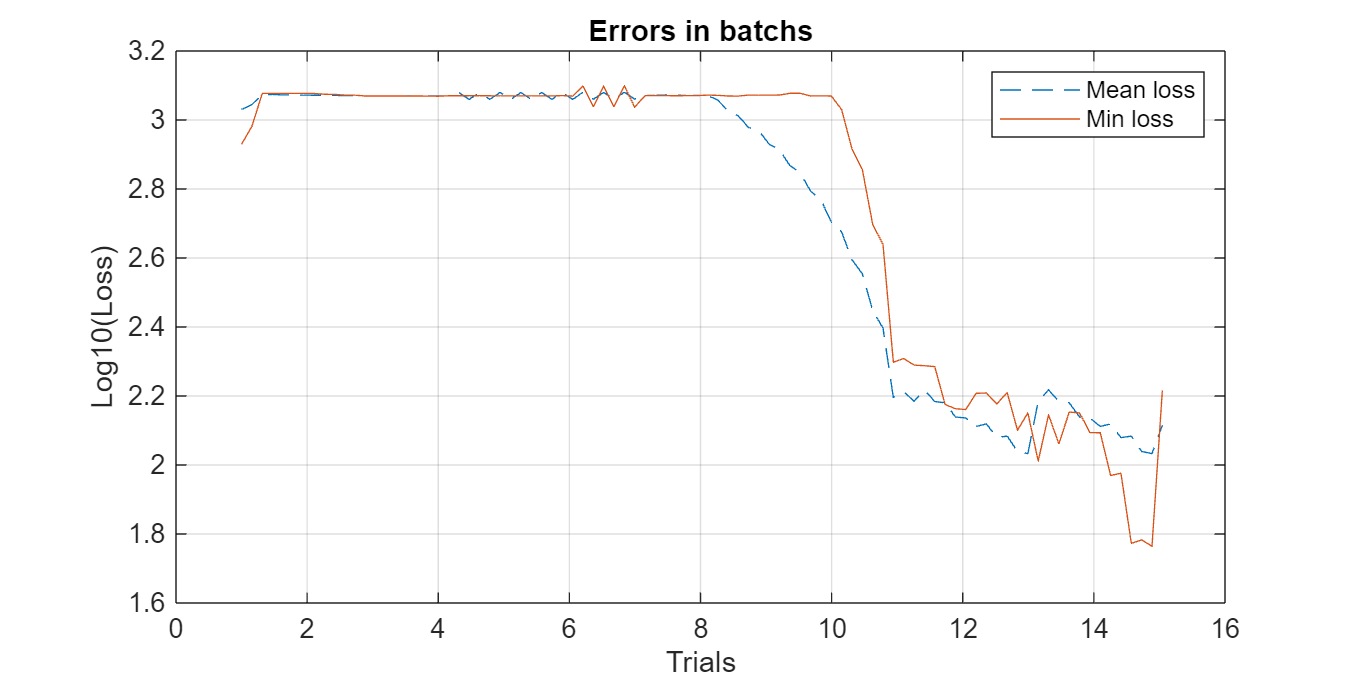

dl.dlPlotBatchErrors(6);

dl.dlLoadOptimal();

		Checkpoint file loaded from dlModels/PN5/Optimal 
---->Optimal [Parallel]


Condition1



	->Single trial running: 
Updating parameters of dlModels/PN5/solve > 

	->Done.


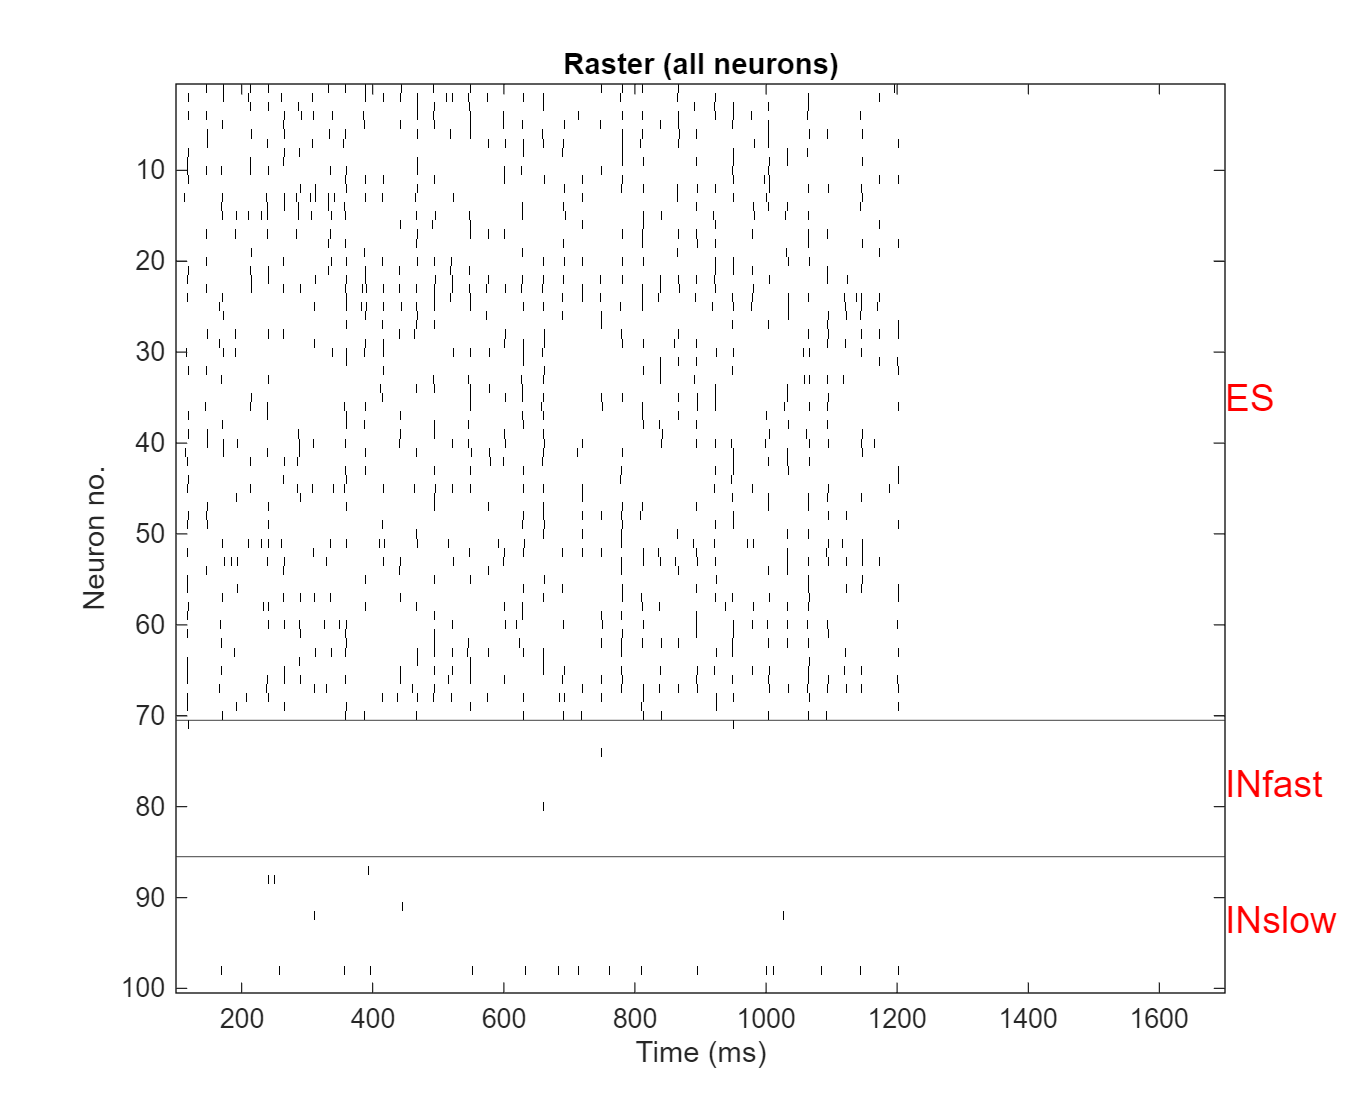

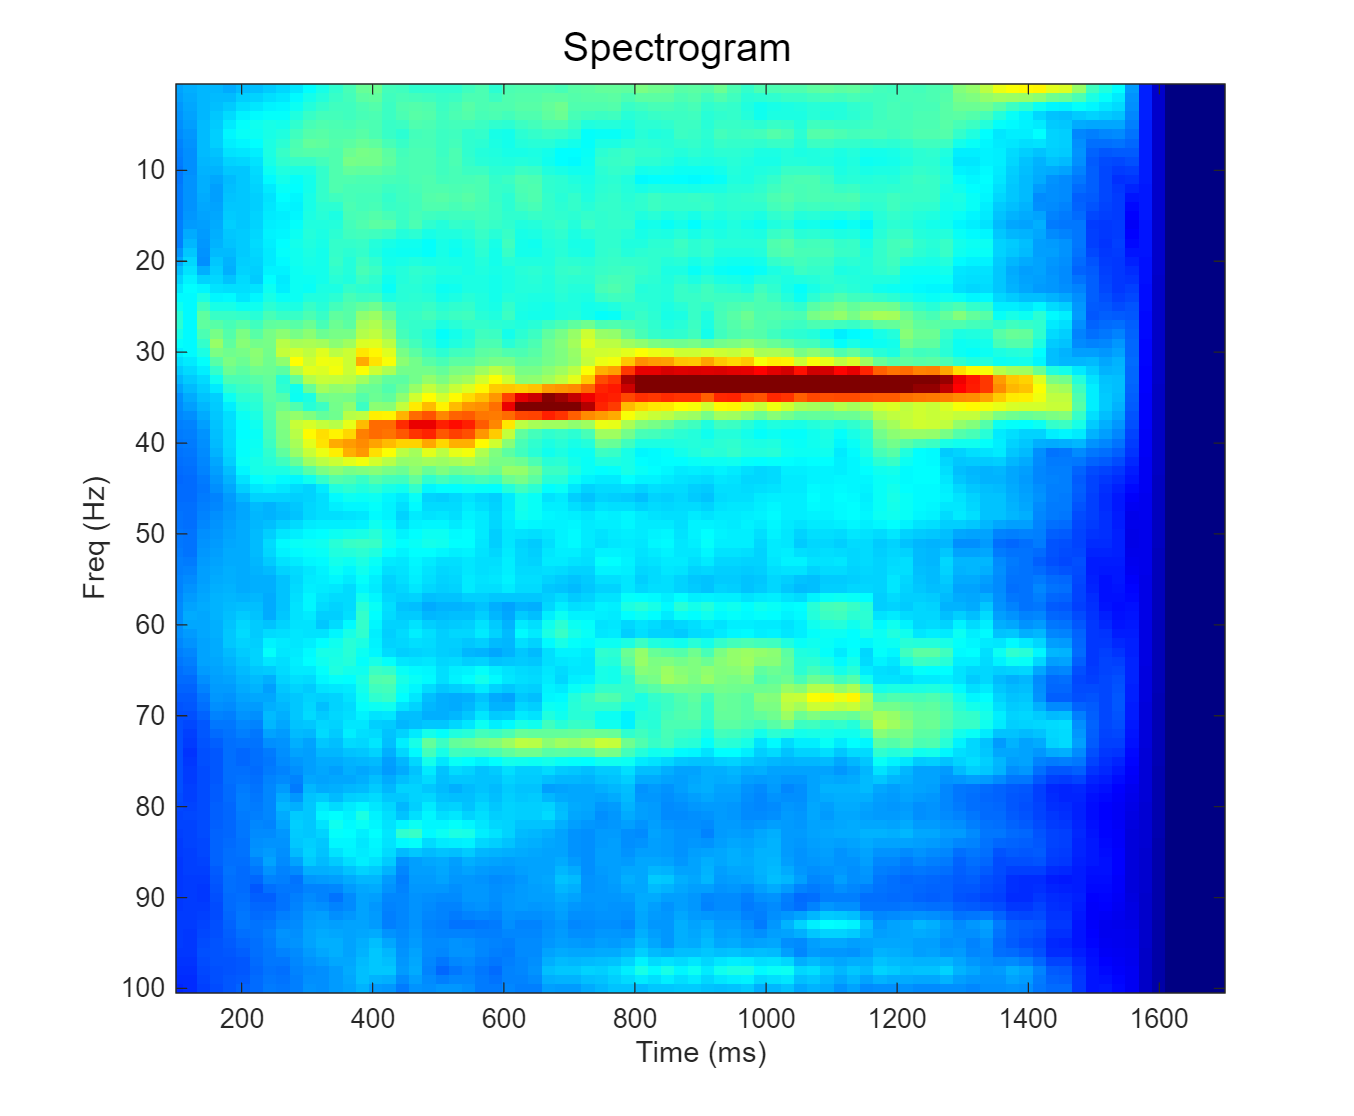

Condition2



	->Single trial running: 
Updating parameters of dlModels/PN5/solve > 

	->Done.


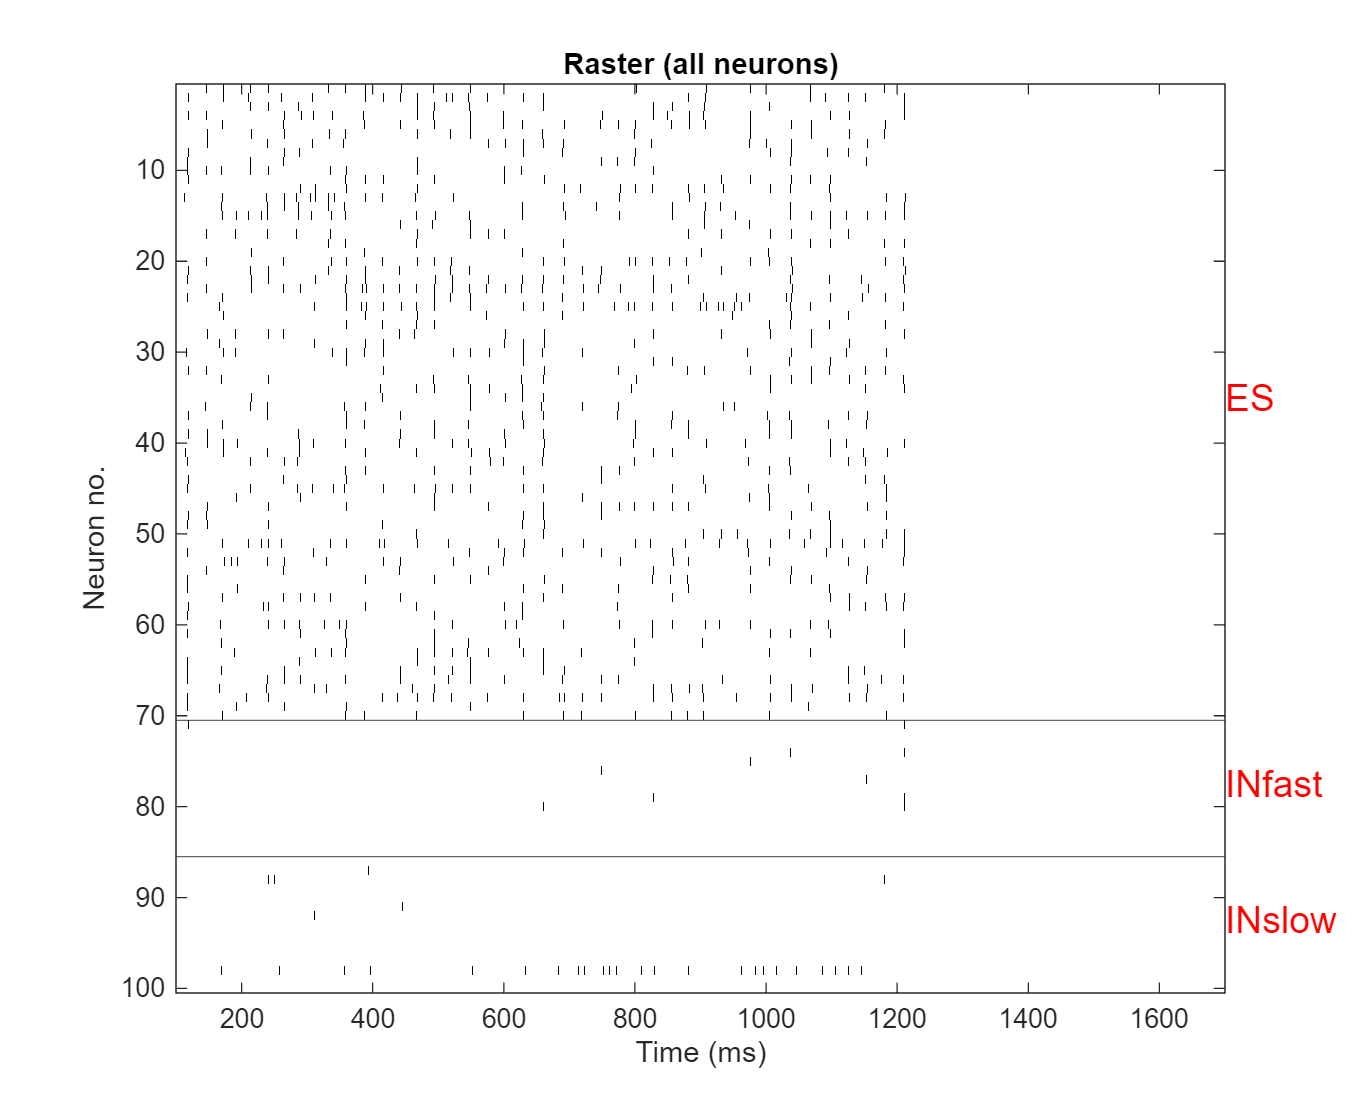

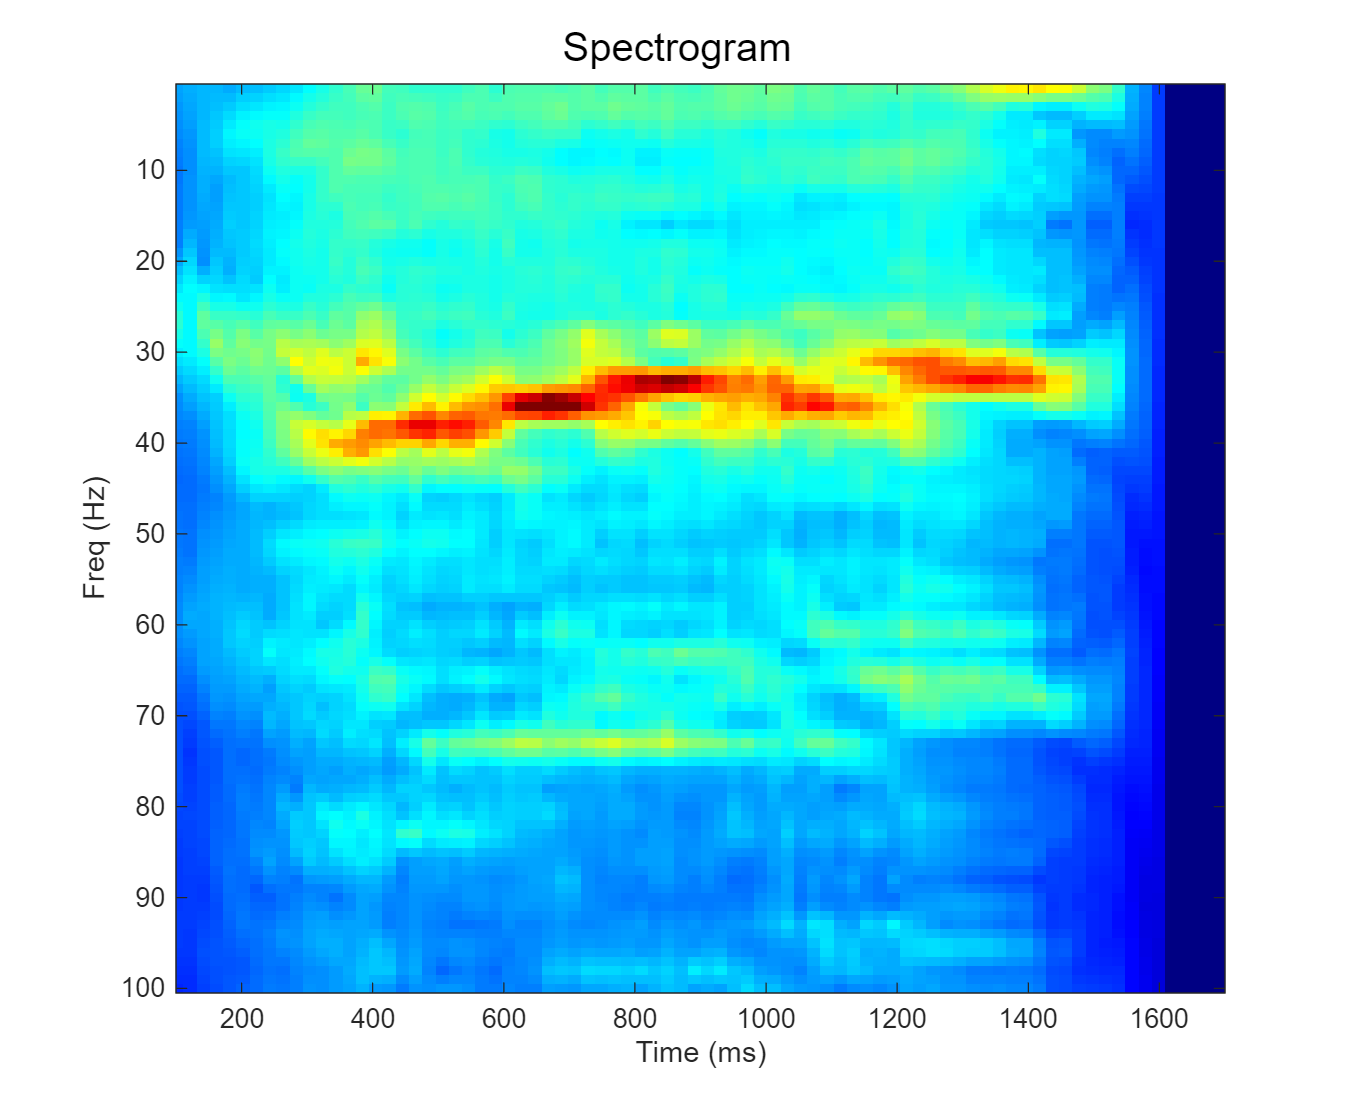

RunDuration = 1700;
[inp1, inp2] = dlOnOffInputs(RunDuration, 700, 1200, 8);
dlInputParameters = {inp1, inp2};

xlims = [100 1700];
clims = [0 3.0];

for i = 1:max(size(dlInputParameters, 2))

    disp("Condition" + num2str(i));
    dl.dlRunSimulation(dlInputParameters{i});%, dlOutputParameters);
    dl.dlRaster(xlims); 
    dl.dlSpectrogram(400, 1, 380, 100, xlims, clims);

end

### Connectivity matrix

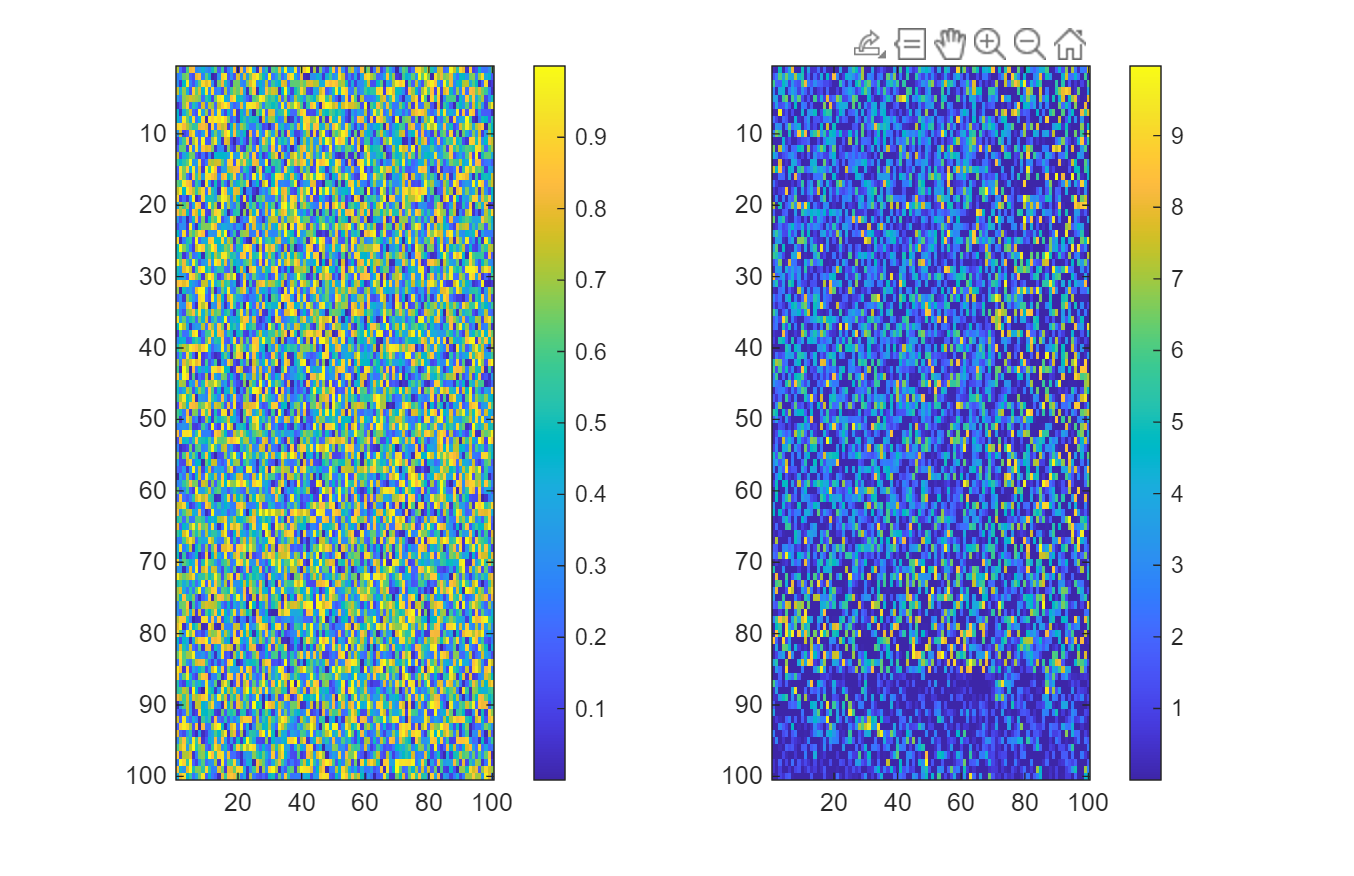

figure("Position", [0 0 1700 1100]);

subplot(1, 2, 1);
imagesc(rand([100, 100]));
colorbar();

subplot(1, 2, 2);
imx = zeros([100, 100]);
imx(1:70, 1:70) = dl.dlParams.ES_ES_iAMPA_netcon;
imx(1:70, 71:85) = dl.dlParams.INslow_ES_iAMPA_netcon;
imx(1:70, 86:100) = dl.dlParams.INfast_ES_iAMPA_netcon;
imx(71:85, 1:70) = dl.dlParams.ES_INslow_iGABAa_netcon;
imx(71:85, 71:85) = dl.dlParams.INslow_INslow_iGABAa_netcon;
imx(71:85, 86:100) = dl.dlParams.INfast_INslow_iGABAa_netcon;
imx(86:100, 1:70) = dl.dlParams.ES_INfast_iGABAa_netcon;
imx(86:100, 71:85) = dl.dlParams.INslow_INfast_iGABAa_netcon;
imx(86:100, 86:100) = dl.dlParams.INfast_INfast_iGABAa_netcon;

imagesc(imx);
colorbar();

### Population time-frequency response

[b, t, f] = dlSpectrogramPlot(dl.dlSignals, 400, 1, 380, 100, 1000, 11, 0);
b(b < 0.2) = 0.1;

figure("Position", [0 0 1700 1000]);
imagesc(b, "XData", t-1000, "YData", f);colormap("jet");

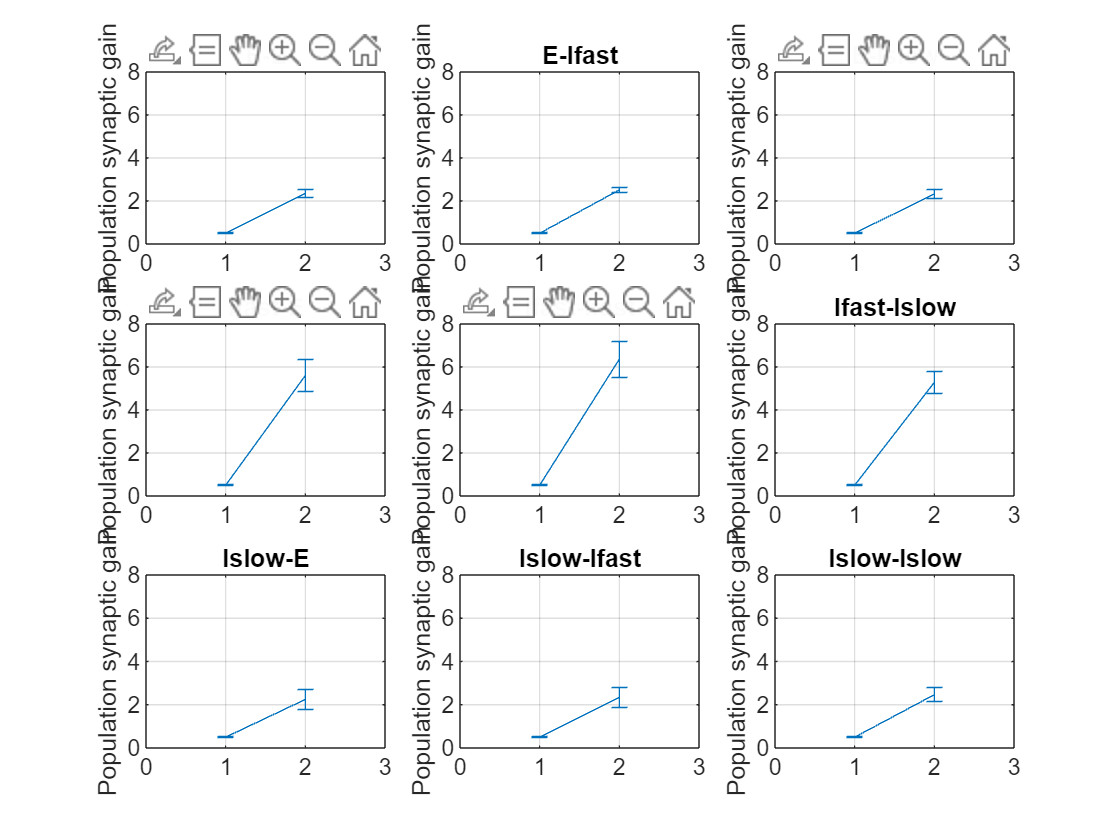

InitState = rand([100, 100]);
CCx = cell(9, 1);

CCx{1} = dl.dlParams.ES_ES_iAMPA_netcon;
CCx{3} = dl.dlParams.INslow_ES_iAMPA_netcon;
CCx{2} = dl.dlParams.INfast_ES_iAMPA_netcon;
CCx{7} = dl.dlParams.ES_INslow_iGABAa_netcon;
CCx{9} = dl.dlParams.INslow_INslow_iGABAa_netcon;
CCx{8} = dl.dlParams.INfast_INslow_iGABAa_netcon;
CCx{4} = dl.dlParams.ES_INfast_iGABAa_netcon;
CCx{6} = dl.dlParams.INslow_INfast_iGABAa_netcon;
CCx{5} = dl.dlParams.INfast_INfast_iGABAa_netcon;

figure;

tlabels_syn = ["E-E", "E-Ifast", "E-Islow", "Ifast-E", "Ifast-Ifast", "Ifast-Islow", "Islow-E", "Islow-Ifast", "Islow-Islow"];
cntp = 0;

for ik = 1:3

    for jk = 1:3

        cntp = cntp + 1;
        subplot(3, 3, cntp);
        FinState = CCx{cntp};
        if contains(tlabels_syn(cntp), "Ifast-")
            FinState = FinState(FinState > max(max(FinState))*0.32); % iFast  synaptic limit penalty
        end
        ilnx1 = [mean(InitState, "all"), mean(FinState, "all")];
        ilnxe1 = [std(std(InitState)), std(std(CCx{cntp}))];
        errorbar(ilnx1, ilnxe1);
        ylim([0 8]);xlim([0 3]);
        ylabel("Population synaptic gain");
        grid("on");title(tlabels_syn(cntp));

    end

end

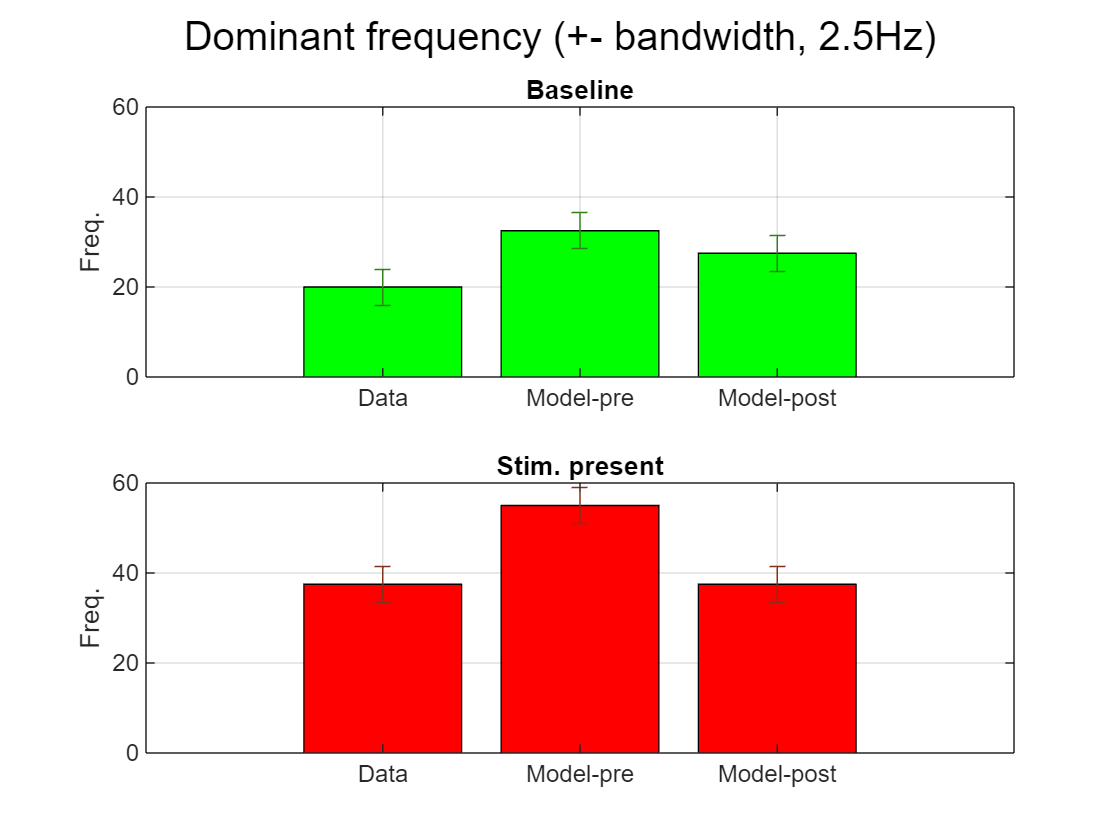

figure;

subplot(2, 1, 1);

ilnx1 = bsl1;
ilnxe1 = bsle1;
bar(1:3, ilnx1, "green");hold("on");
errorbar(ilnx1, ilnxe1, "LineStyle", "none", "Color", [0.2 0.5 0.1]);
ylim([0 60]);
ylabel("Freq.");
xticklabels(["Data", "Model-pre", "Model-post"]);
grid("on");
title("Baseline");

subplot(2, 1, 2);

ilnx1 = bsl2;
ilnxe1 = bsle2;
bar(ilnx1, "red");hold("on");
errorbar(ilnx1, ilnxe1, "LineStyle", "none", "Color", [0.5 0.2 0.1]);
ylim([0 60]);
ylabel("Freq.");
xticklabels(["Data", "Model-pre", "Model-post"]);
grid("on");
title("Stim. present");

sgtitle("Dominant frequency (+- bandwidth, 2.5Hz)");

# End